# ELEN 133 Homework 8 -- Ayden Dauenhauer

## Question 6

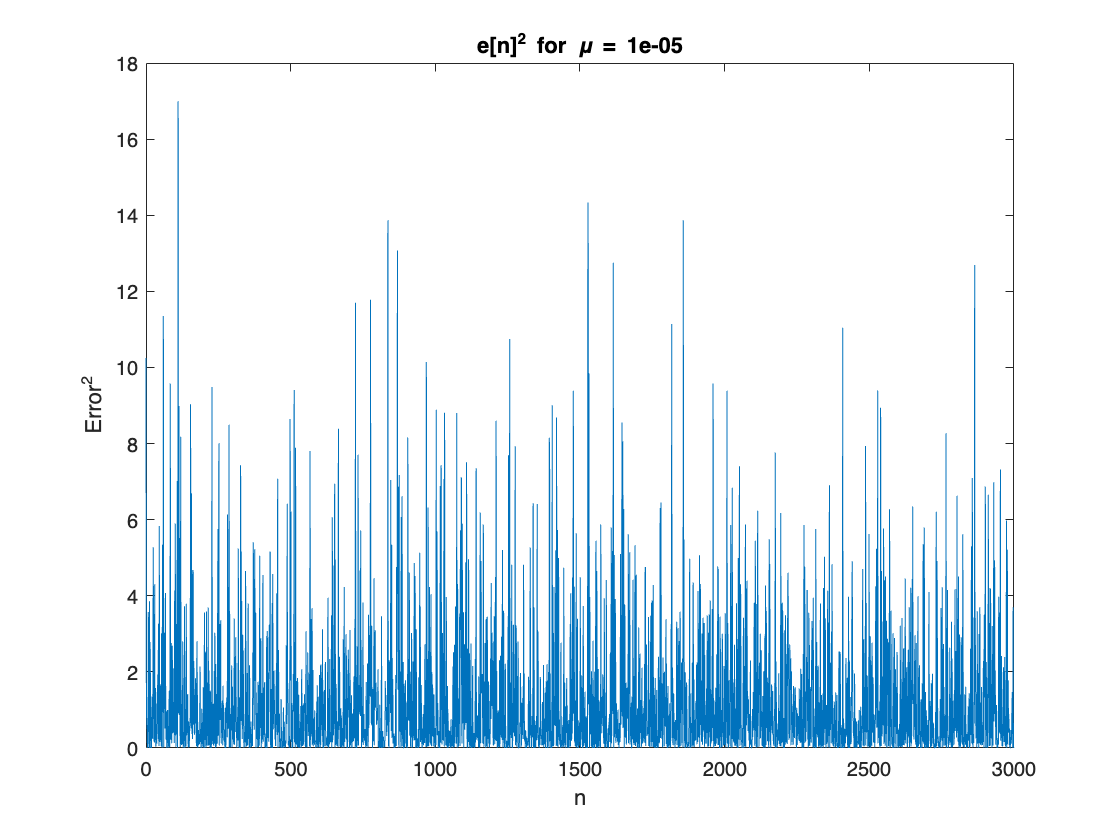

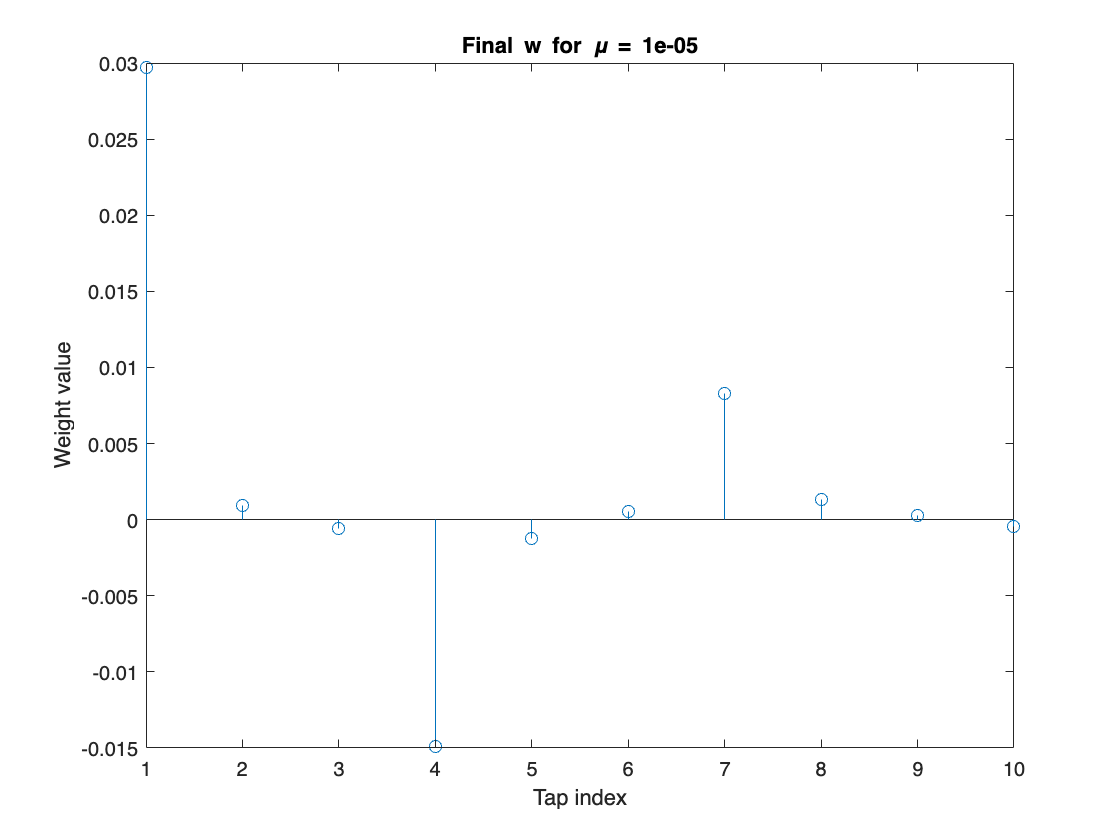

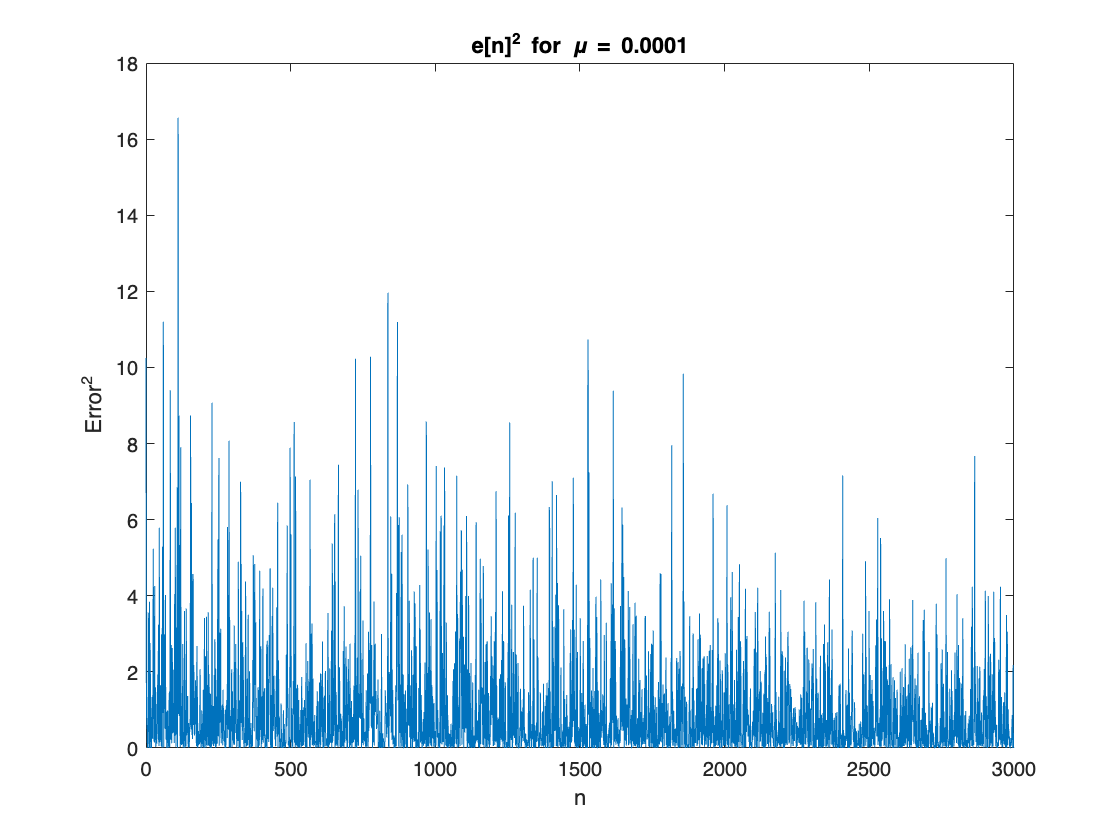

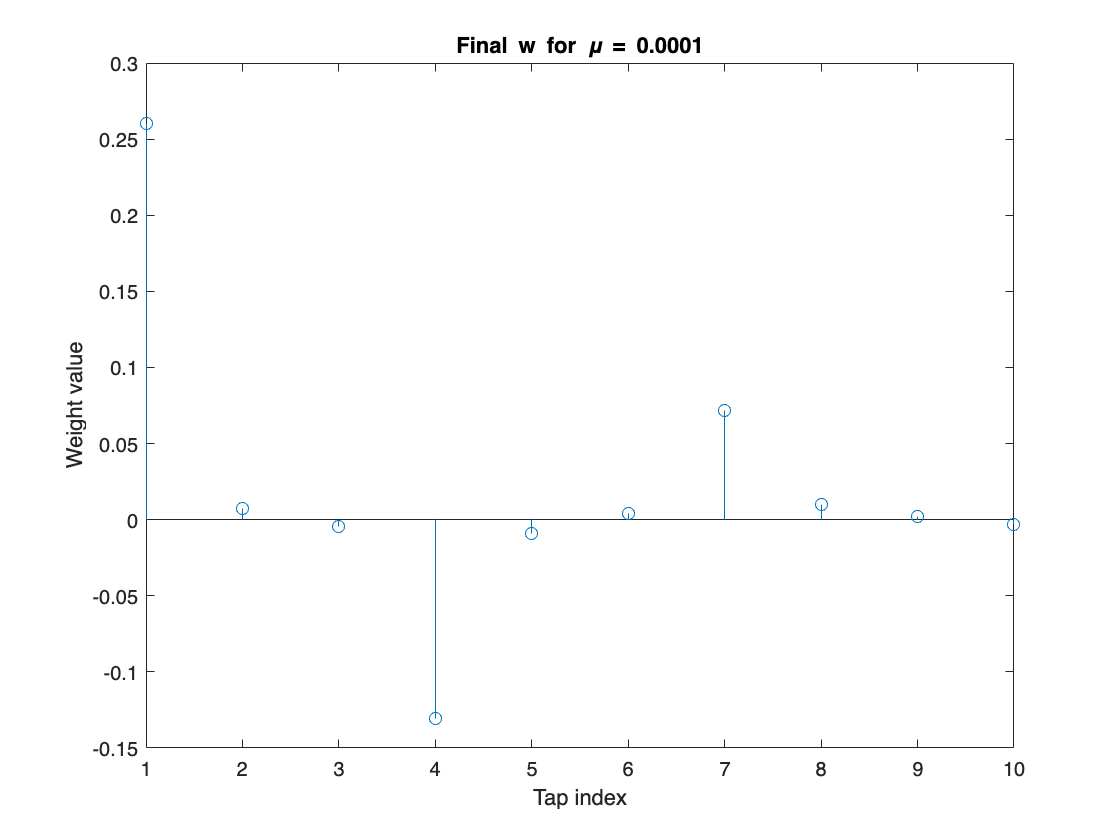

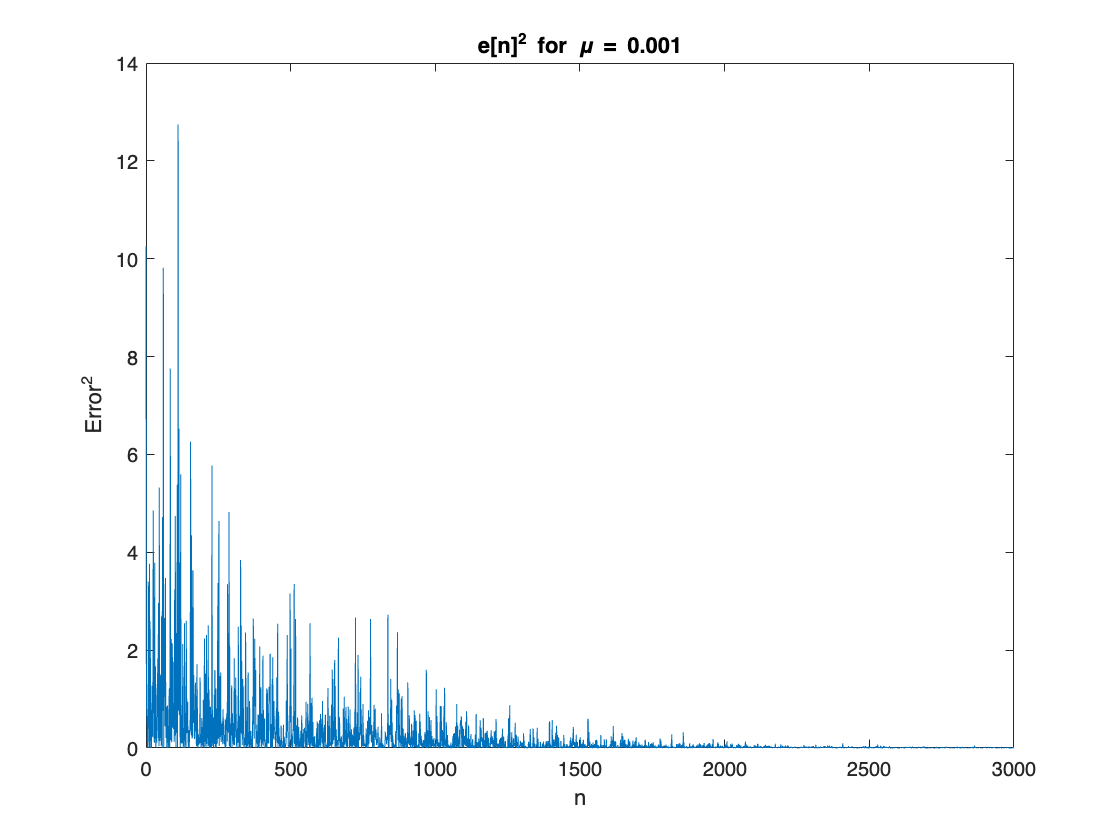

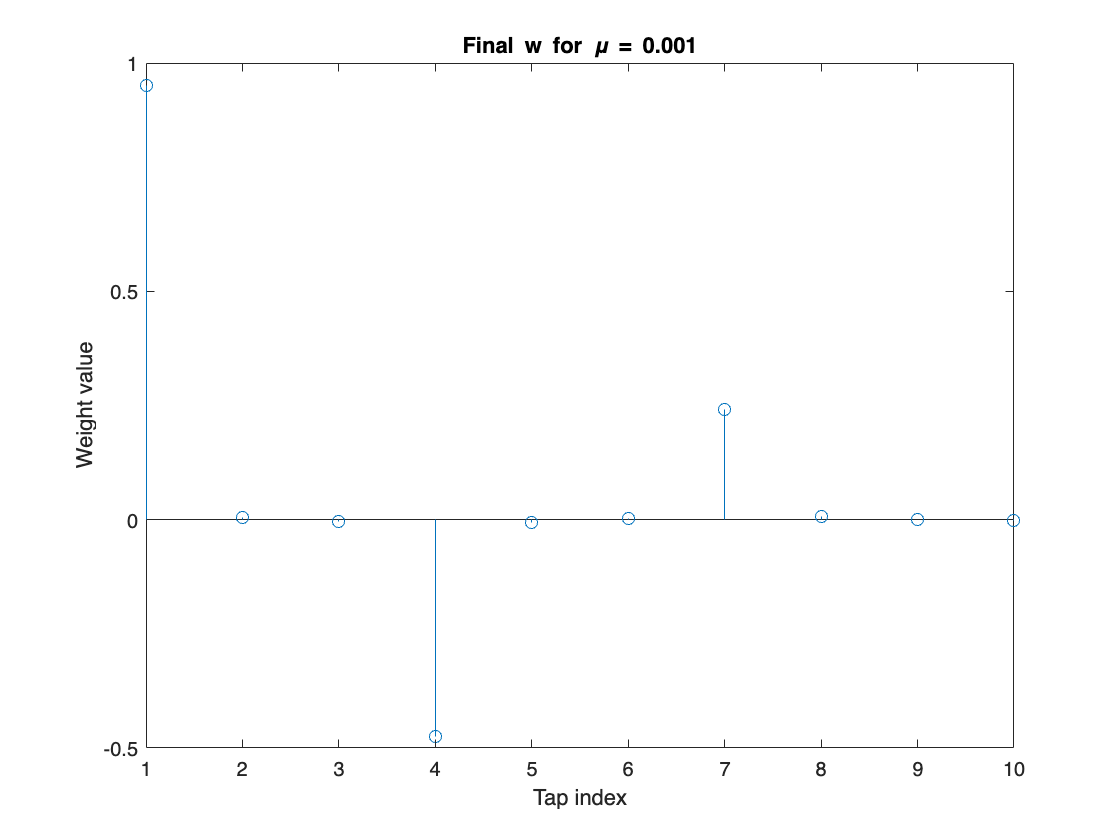

h = [1, 0, 0, -0.5, 0, 0, 0.25];
M = 10;
mu_vals = [1e-5, 1e-4, 1e-3];
N = 3000 + M - 1;
x = randn(1, N);

d_full = conv(x, h);
d = d_full(1:N);

for i = 1:length(mu_vals)
    mu = mu_vals(i);
    w = zeros(1, M);
    e2 = zeros(1, N - M + 1);
    w_history = zeros(M, N - M + 1);

    for n = M:N
        x_vec = x(n:-1:n - M + 1);
        y = w * x_vec';
        e = d(n) - y;
        w = w + mu * e * x_vec;
        e2(n - M + 1) = e^2;
        w_history(:, n - M + 1) = w';
    end

    figure;
    plot(0:length(e2)-1, e2);
    title(['e[n]^2 for \mu = ', num2str(mu)]);
    xlabel('n');
    ylabel('Error^2');

    figure;
    stem(w);
    title(['Final w for \mu = ', num2str(mu)]);
    xlabel('Tap index');
    ylabel('Weight value');
end

**How is the final value of w[0] related to the adaptation constant? What would you expect the value of w[0] to be for u = 10−6?**

    w[0] = 1 since its converging closer and closer to 1 each time.

**How is this related to your answer to part (b)?**

    w[0] = 1 still, but it converges faster.

## Question 7

**If the input is a*randn(1,N) instead of randn(1,N), how will this affect the outer product?**

    The outer product scales by a^2.

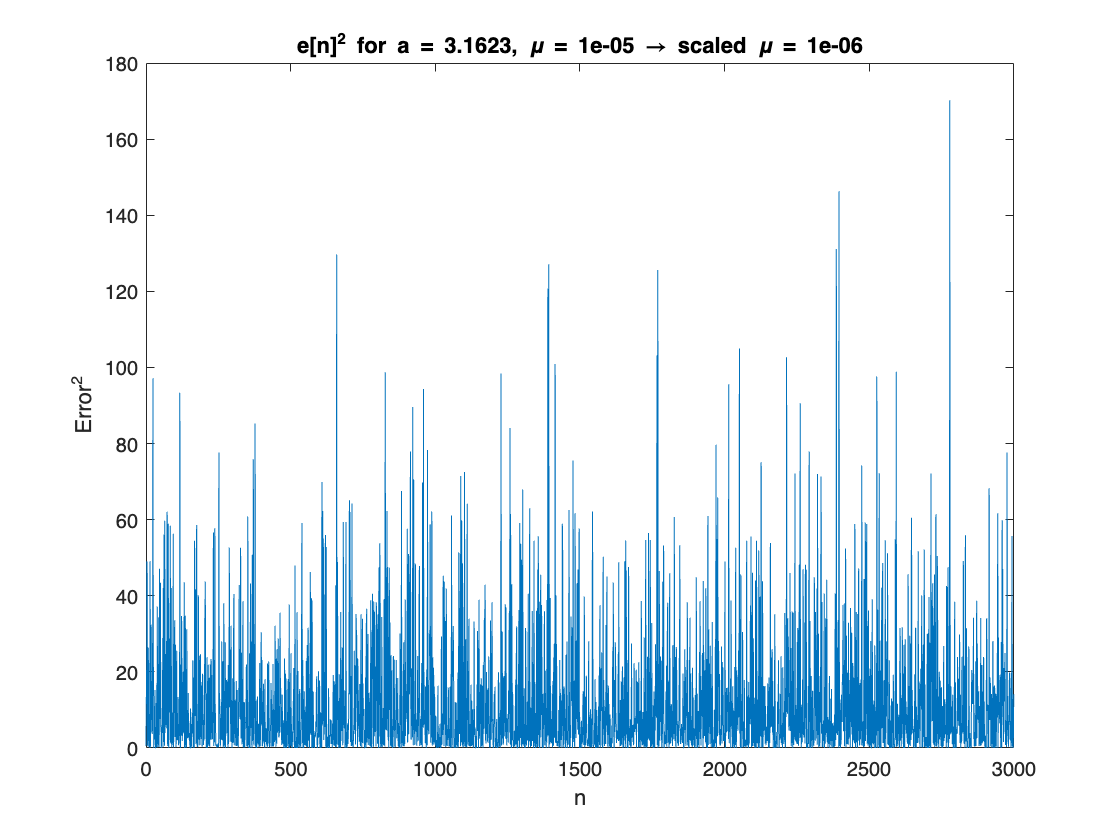

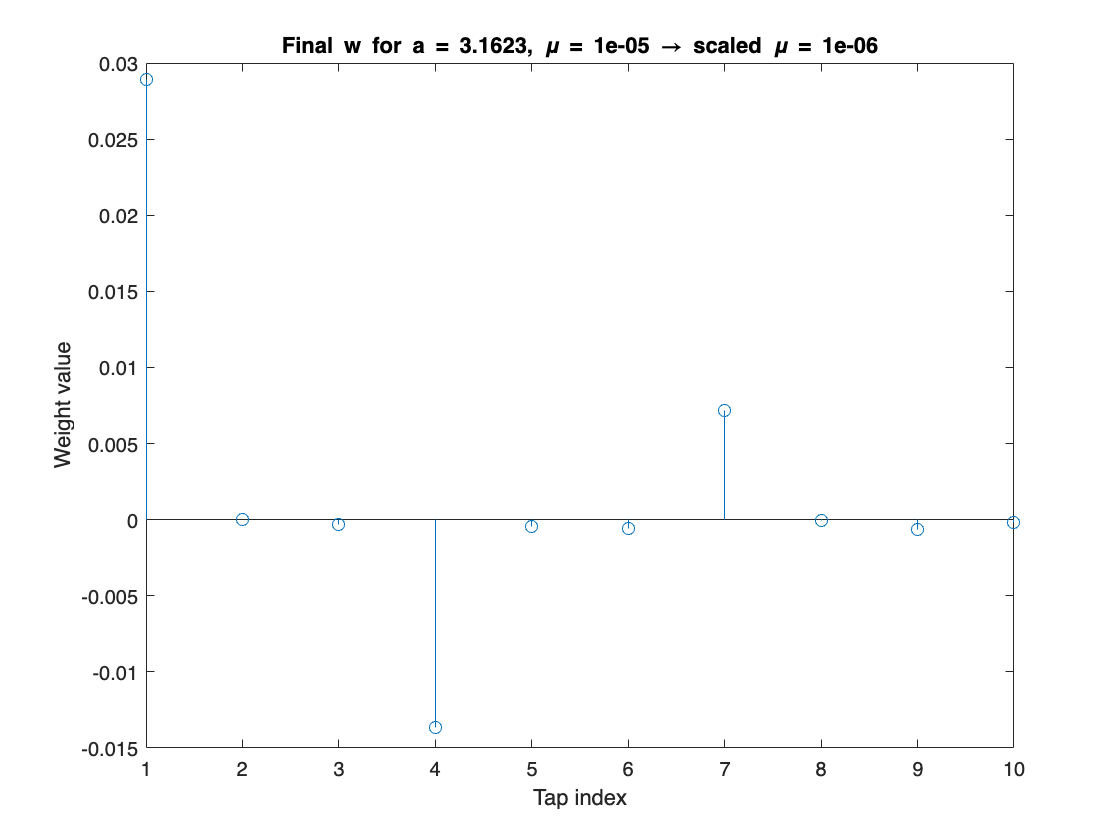

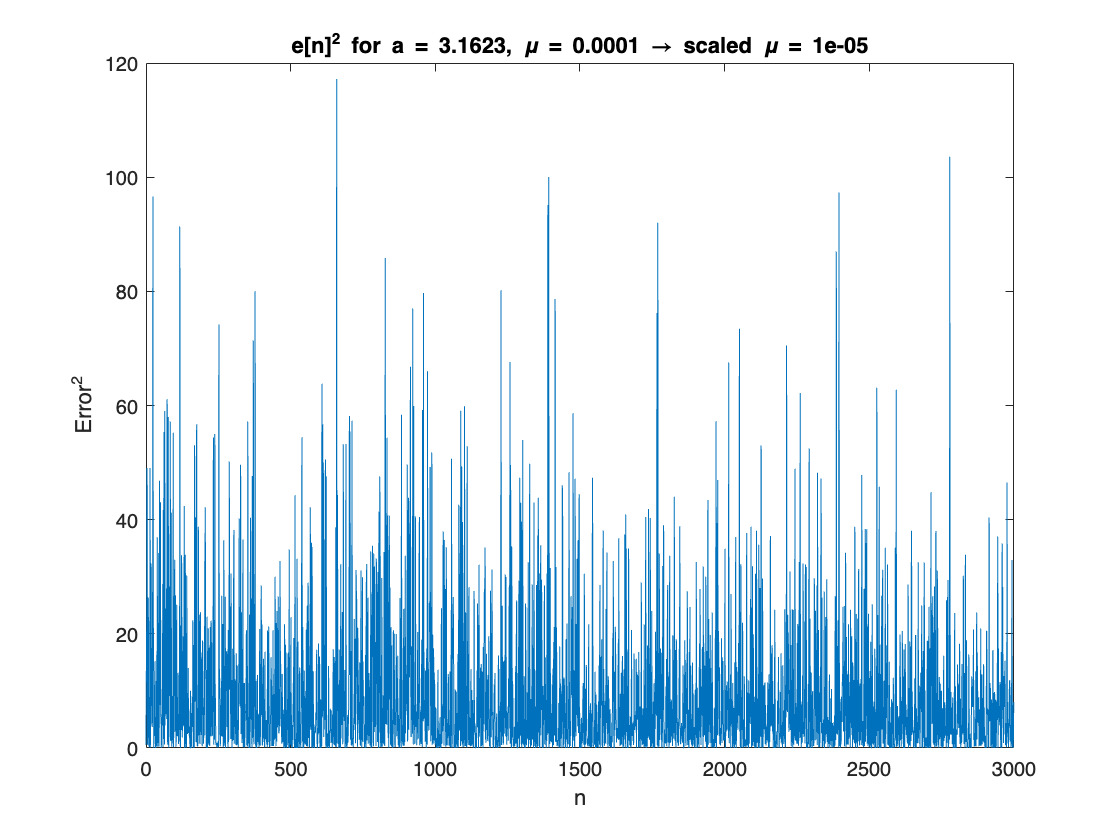

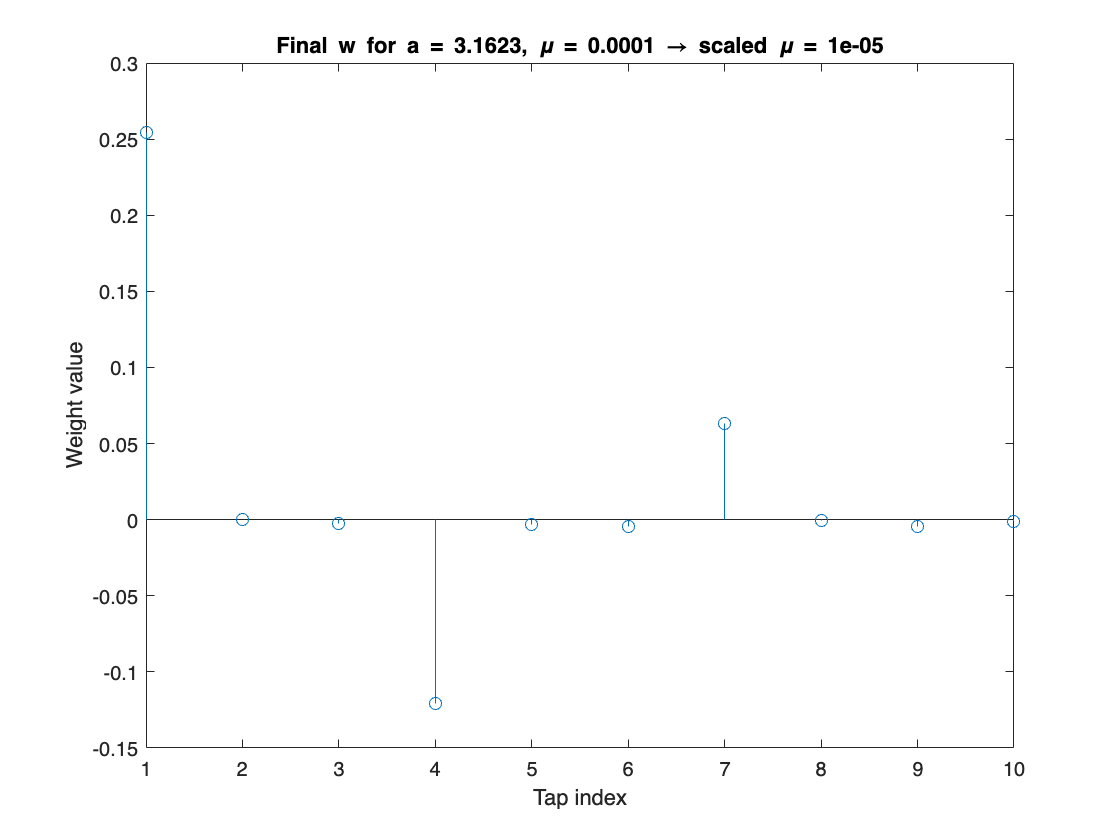

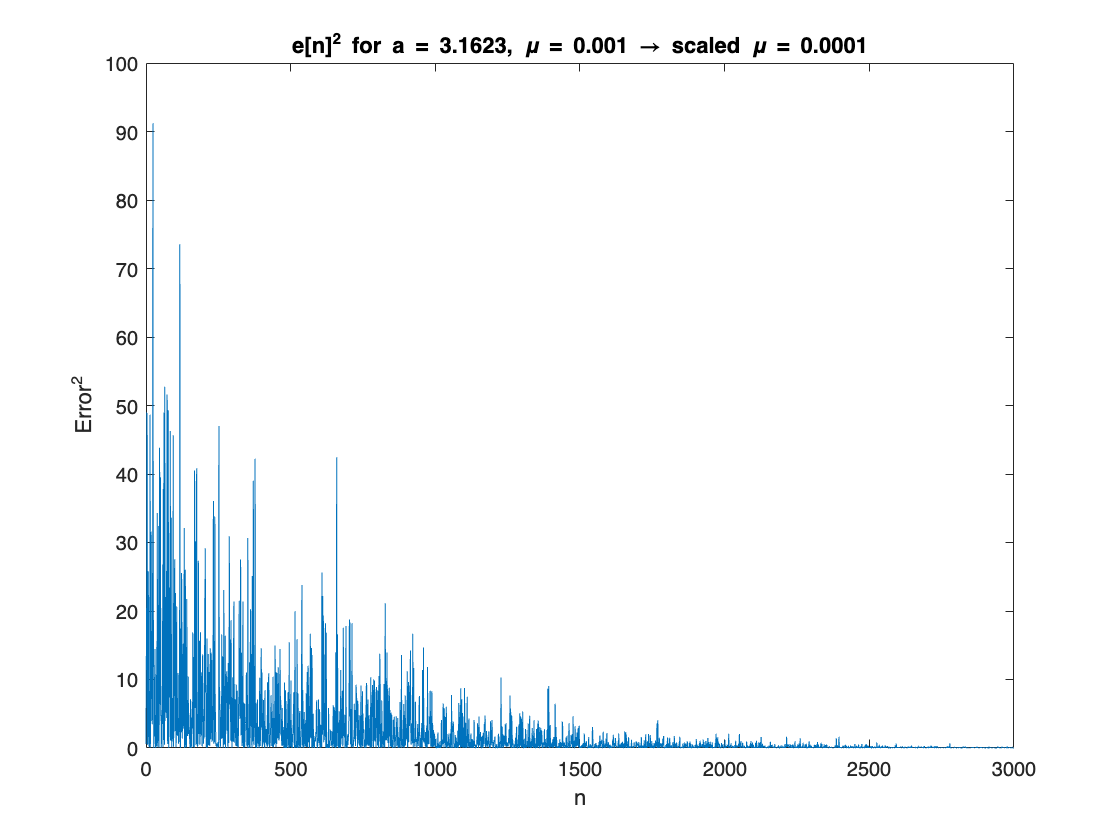

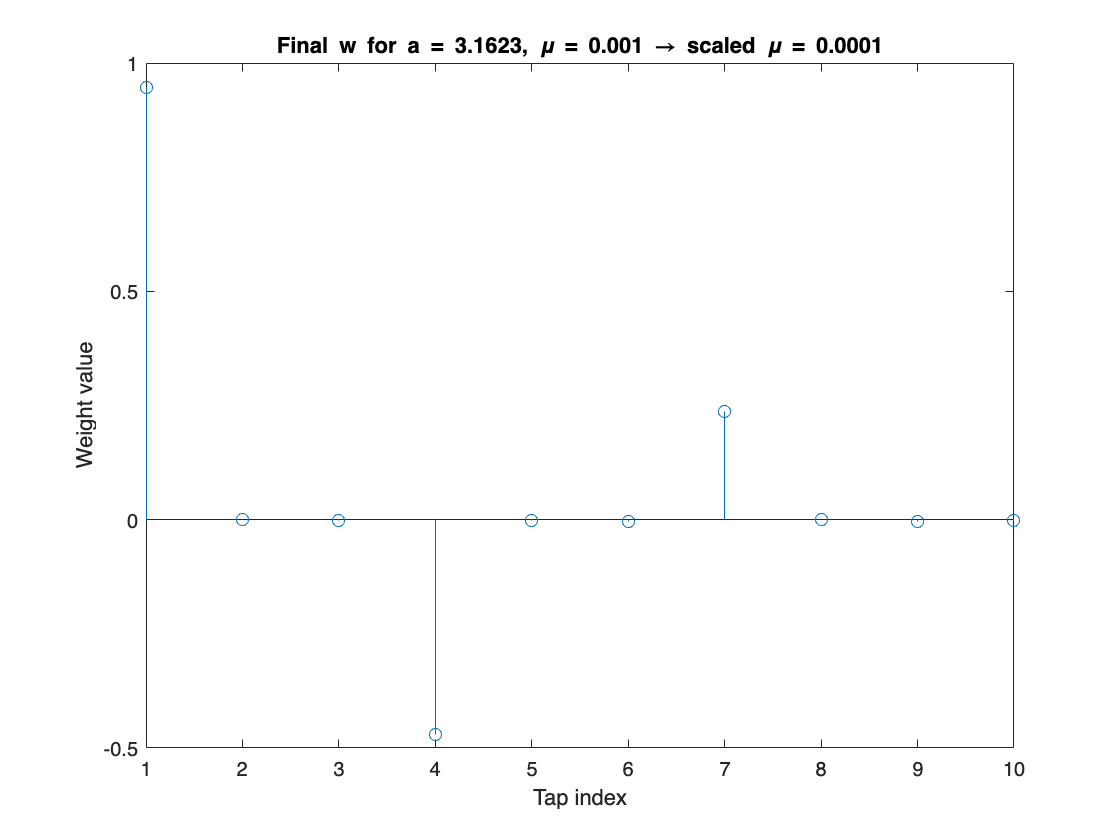

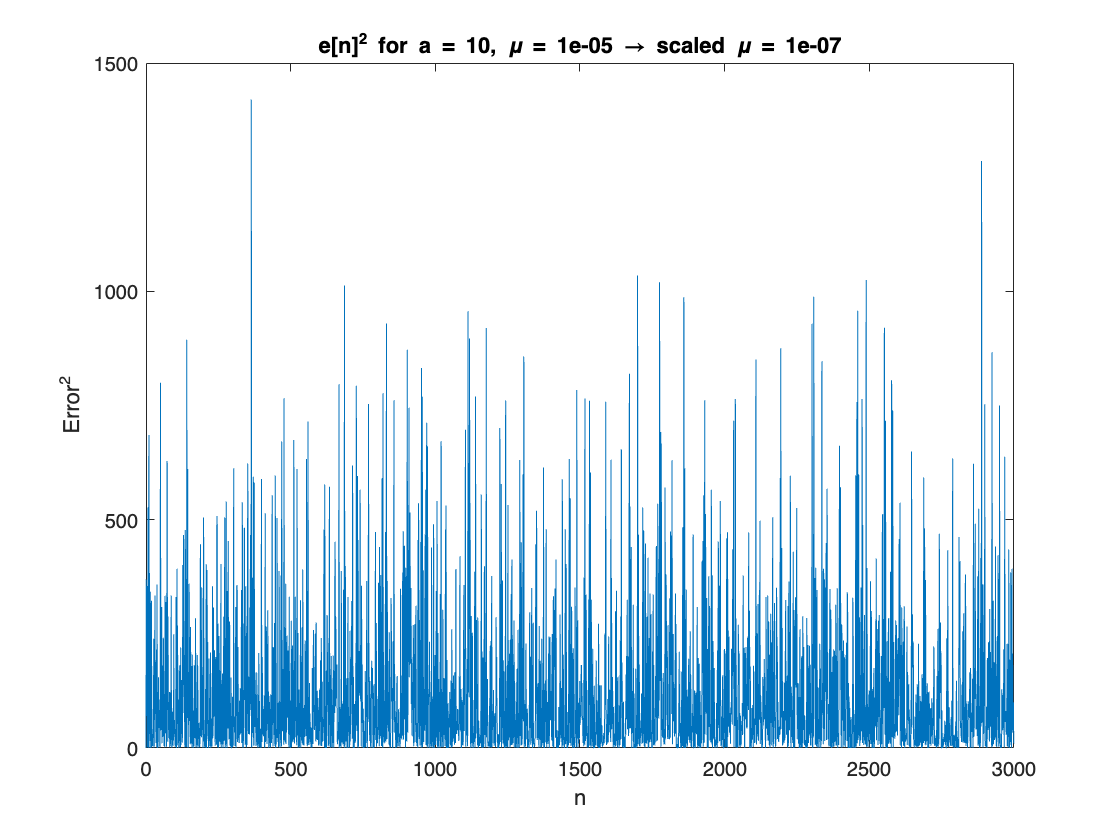

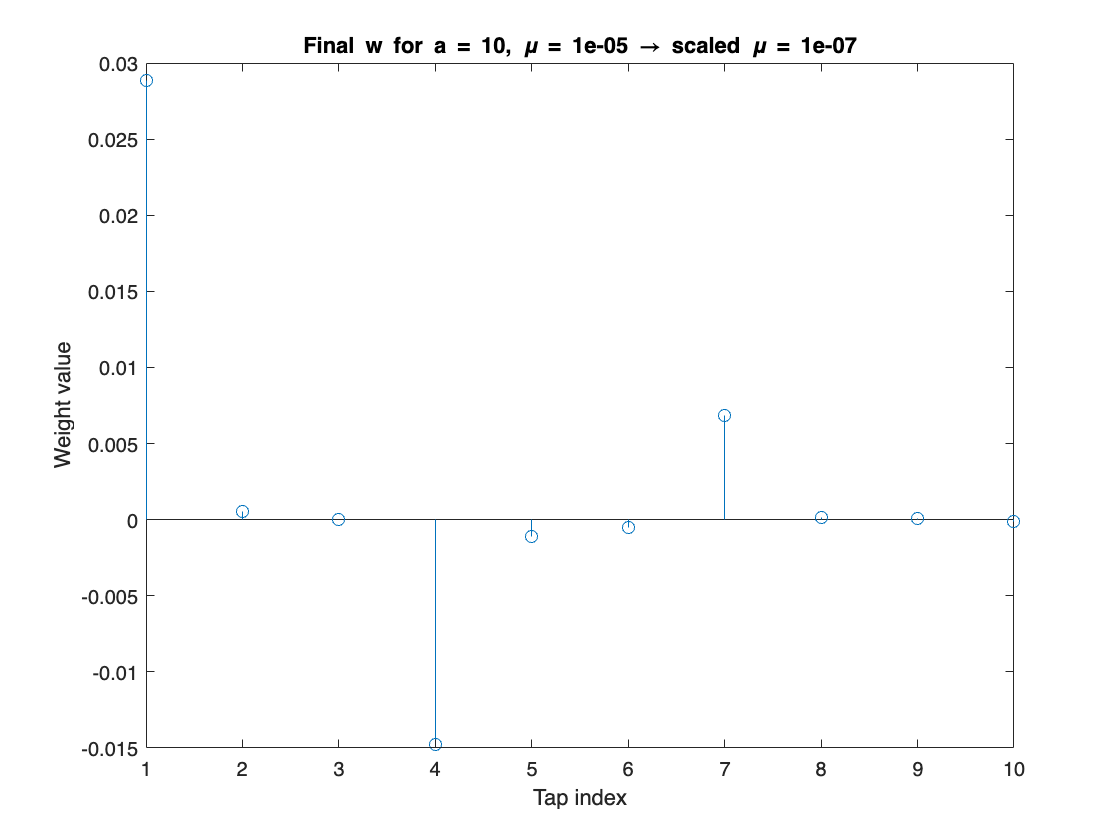

a_vals = [sqrt(10), 10];
mu_vals_base = [1e-5, 1e-4, 1e-3];

for j = 1:length(a_vals)
    a = a_vals(j);
    x = a * randn(1, N);
    d_full = conv(x, h);
    d = d_full(1:N);

    for i = 1:length(mu_vals_base)
        mu = mu_vals_base(i);
        mu_scaled = mu / a^2;

        w = zeros(1, M);
        e2 = zeros(1, N - M + 1);
        w_history = zeros(M, N - M + 1);

        for n = M:N
            x_vec = x(n:-1:n - M + 1);
            y = w * x_vec';
            e = d(n) - y;
            w = w + mu_scaled * e * x_vec;
            e2(n - M + 1) = e^2;
            w_history(:, n - M + 1) = w';
        end

        figure;
        plot(0:length(e2)-1, e2);
        title(['e[n]^2 for a = ', num2str(a), ', \mu = ', num2str(mu), ' → scaled \mu = ', num2str(mu_scaled)]);
        xlabel('n');
        ylabel('Error^2');

        figure;
        stem(w);
        title(['Final w for a = ', num2str(a), ', \mu = ', num2str(mu), ' → scaled \mu = ', num2str(mu_scaled)]);
        xlabel('Tap index');
        ylabel('Weight value');
    end
end

**What is the relationship between the adaptation constants which produce similar results here and in Problem 6a?**

    The scaled u is u / a^2.